# Composición de Rotaciones

Cuando se realizan múltiples rotaciones es importante tener en cuenta si las rotaciones se hace sobre el sistema de referencia fijo o si se van realizando progresivamente con respecto a sistemas móviles.

A continuación se definierán tres ángulos que corresponden a tres roatciones indeendientes

ang_1 = 1.328408;
ang_2 = -0.521592;
ang_3 = 0.658408;
axes_o = [1 0 0;
          0 1 0;
          0 0 1]; %ejes iniciales

## Matrices de rotación

R_x = [1 0 0; ...
        0 cos(ang_1) -sin(ang_1); ...
        0 sin(ang_1) cos(ang_1)]

R_x =     1.0000         0         0
         0    0.2400   -0.9708
         0    0.9708    0.2400


R_y = [cos(ang_2) 0 sin(ang_2); ...
        0 1 0; ...
        -sin(ang_2) 0 cos(ang_2)]

R_y =     0.8670         0   -0.4983
         0    1.0000         0
    0.4983         0    0.8670


R_z = [cos(ang_3) -sin(ang_3) 0; ...
       sin(ang_3) cos(ang_3) 0;
       0 0 1]

R_z =     0.7910   -0.6119         0
    0.6119    0.7910         0
         0         0    1.0000


## Rotaciones sobre ejes del sistema fijo

Las rotaciones se aplican sobre los ejes x,y,z fijos. En este caso las matrices se pre-multiplican.

R_f1 = R_z*R_y*R_x

R_f1 =     0.6858   -0.5294    0.4994
    0.5305   -0.1061   -0.8410
    0.4983    0.8417    0.2081


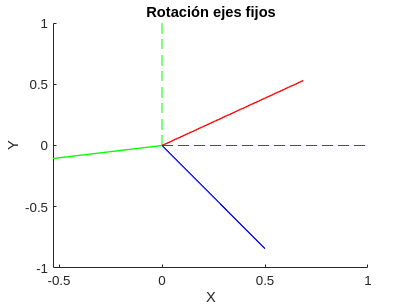

axes_f1 = R_f1*axes_o;
%grafica
figure(1)
title('Rotación ejes fijos')
xlabel('X')
ylabel('Y')
zlabel('Z')
hold on
%Ejes fijos
plot3([0 1],[0 0],[0 0],'--r','LineWidth',0.5)
plot3([0 0],[0 1],[0 0],'--g','LineWidth',0.5)
plot3([0 0],[0 0],[0 1],'--b','LineWidth',0.5)

%Ejes rotados
plot3([0 axes_f1(1,1)],[0 axes_f1(2,1)],[0 axes_f1(3,1)],'-r','LineWidth',1)
plot3([0 axes_f1(1,2)],[0 axes_f1(2,2)],[0 axes_f1(3,2)],'-g','LineWidth',1)
plot3([0 axes_f1(1,3)],[0 axes_f1(2,3)],[0 axes_f1(3,3)],'-b','LineWidth',1)
hold off

## Rotaciones sobre ejes sistemas moviles

Las rotaciones se aplicarán sobre los ejes que se van moviendo. En este caso las matrices se post-multiplican.

R_f2 = R_x*R_y*R_z

R_f2 =     0.6858   -0.5305   -0.4983
   -0.2357    0.4858   -0.8417
    0.6886    0.6947    0.2081


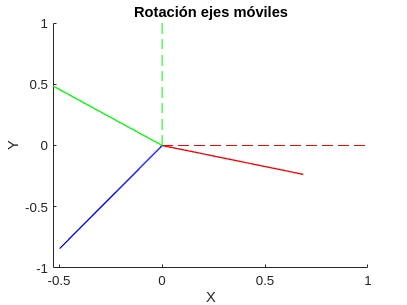

axes_f2 = R_f2*axes_o;
%grafica
figure(2)
title('Rotación ejes móviles')
xlabel('X')
ylabel('Y')
zlabel('Z')
hold on
%Ejes fijos
plot3([0 1],[0 0],[0 0],'--r','LineWidth',0.5)
plot3([0 0],[0 1],[0 0],'--g','LineWidth',0.5)
plot3([0 0],[0 0],[0 1],'--b','LineWidth',0.5)

%Ejes rotados
plot3([0 axes_f2(1,1)],[0 axes_f2(2,1)],[0 axes_f2(3,1)],'-r','LineWidth',1)
plot3([0 axes_f2(1,2)],[0 axes_f2(2,2)],[0 axes_f2(3,2)],'-g','LineWidth',1)
plot3([0 axes_f2(1,3)],[0 axes_f2(2,3)],[0 axes_f2(3,3)],'-b','LineWidth',1)
hold off